# Calculate cross section at non-interacting field

## Set atom and magnetic field

setTestConfig(true)

% atom
atom = Alkali("Lithium7");

% B fielsigd
hfB = 720e-4; %high feshbach field
bField = MagneticField(bias=[0;0;hfB]);
bField = {bField};
[stateList,U] = atom.D2.BiasDressedStateList(bField{1});
U = {U};

## Set cross section simulation

% resonant frequency
freq =     stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).Energy ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Energy ...
    + stateList(stateList.F==3 & stateList.MF==0 & stateList.IsExcited == true,:).EnergyShift ...
    - stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).EnergyShift;
Isat = atom.CyclerSaturationIntensity;

% initial condition
psi = zeros(atom.D2.NNState,1)

psi =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


psi(stateList(stateList.F==1 & stateList.MF==1 & stateList.IsExcited == false,:).Index) = 1;
ic = InitialCondition("MeSim");
ic.WaveFunction = psi;

% scan saturaction parameter
nLaser = 12;
sMin = 0.01;
sMax = 0.5;
sList = linspace(sMin,sMax,nLaser);

% set laser
laser = cell(1,nLaser);
angle = 10;
for ii = 1:nLaser
laser{ii} = Laser( ...
    frequency = freq,...
    direction = [0;0;1],...
    polarization = sphericalBasis(1),...
    intensity = sList(ii)*Isat ...
    );
laser{ii}.rotateToAngle([angle/180*pi,0]);
end

% simulation objects
me = MeSim("crossSectionLi7",...
    initialCondition=ic,...
    laser=laser,...
    magneticField=bField,...
    transformation=U,...
    rotatingFrequency=freq,...
    totalTime = 5e-6,...
    timeStep = 5e-12);
me.Description = "Calculate Li7 cross section for high-field.";
me.update;
me.start;

All runs are completed.


## Plot

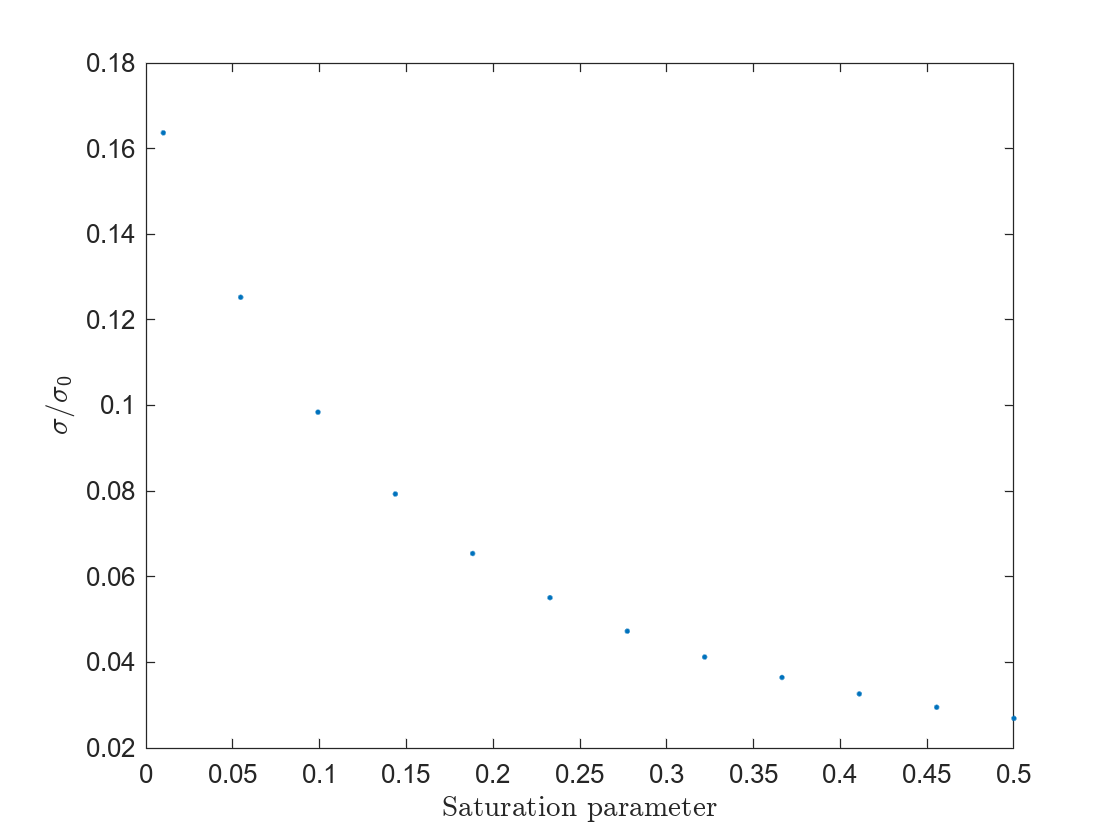


sList0 = 0:0.005:0.5;
sigmaLis1 = 1./(1+sList0);
sigmaLis2 = ones(1,numel(sList0)) / 3;

% plot cross section
trialNumber = 16;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp,s1] = obj.showCrossSection;

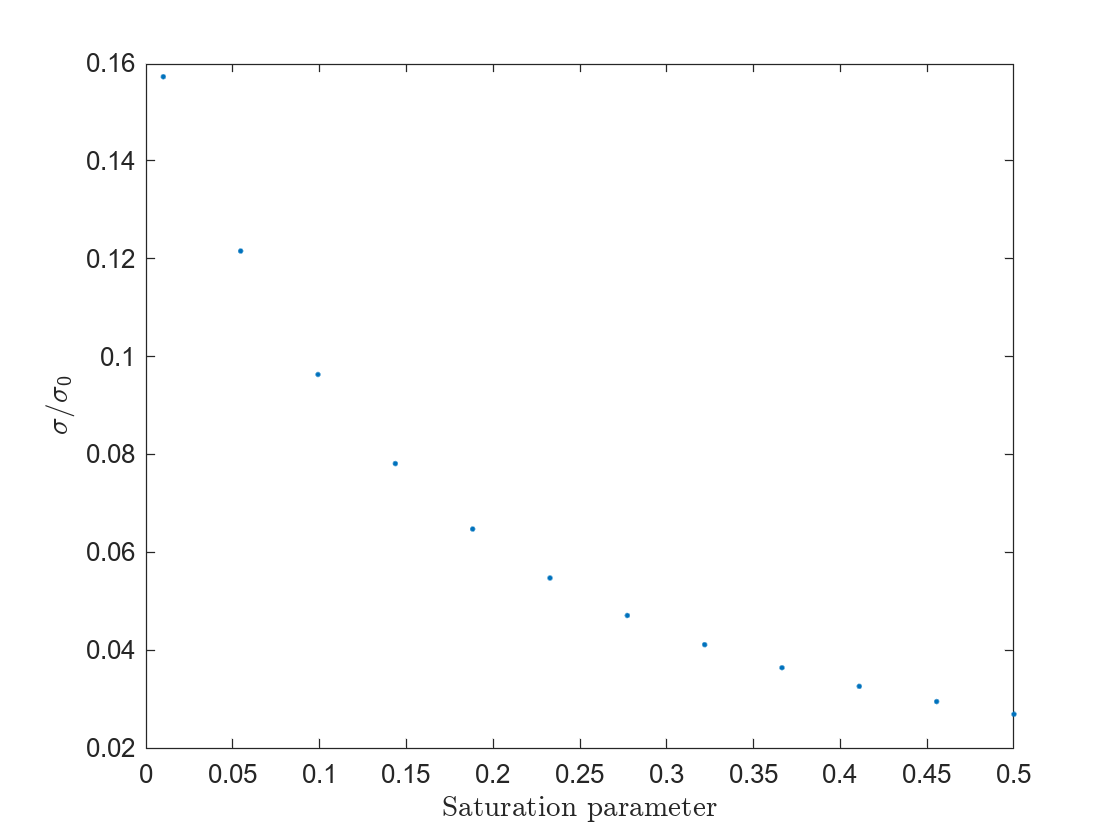


trialNumber = 17;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp,s2] = obj.showCrossSection;

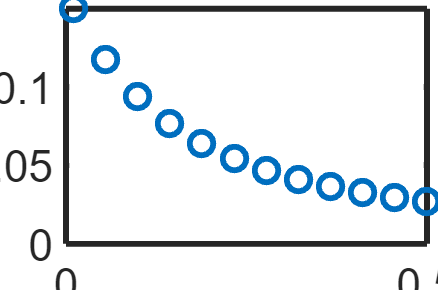


trialNumber = 18;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
[sp,s3] = obj.showCrossSection;

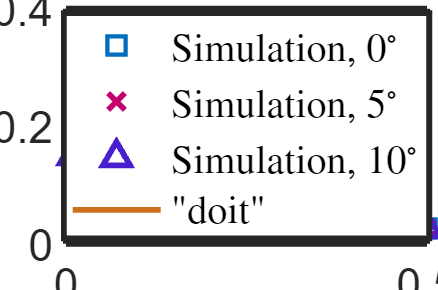


% trialNumber = 10;
% obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
% [sp,s4] = obj.showCrossSection;

close(figure(2048))
figure(2048)
plot(sp,s1,'.',sp,s2,'.',sp,s3,'.',sList0,sigmaLis2)
legend("Simulation, $0^{\circ}$",...
    "Simulation, $5^{\circ}$",...
    "Simulation, $10^{\circ}$",...
    """doit""")
xlabel("Saturation parameter",Interpreter="latex")
ylabel("$\sigma / \sigma_0$",Interpreter="latex")
render

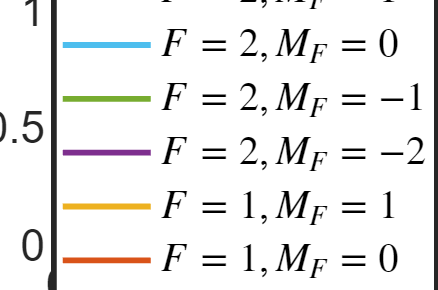


%plot population
trialNumber = 18;
obj = loadTrial(createReader("simulation"),"master_equation_simulation",trialNumber);
obj.SimRun(6).showPopulationGround
saveas(gcf,fullfile(obj.DataAnalysisPath,"popGround.png"),'png')

me.update